%In this script we model Acer glabrum v. glabrum like we did in the PCE 
%paper and then vary all properties as reported in Lens et al., 2011 and 
%check how much of the variation in the VC is due to pit membrane properties.

## Load VC data

AgdVC = readtable('..\Acer VCs.xlsx', 'Sheet',1, 'PreserveVariableNames', true);
AggVC = readtable('..\Acer VCs.xlsx', 'Sheet',2, 'PreserveVariableNames', true);
AgVC = readtable('..\Acer VCs.xlsx', 'Sheet',3, 'PreserveVariableNames', true);
AnVC = readtable('..\Acer VCs.xlsx', 'Sheet',4, 'PreserveVariableNames', true);
ApVC = readtable('..\Acer VCs.xlsx', 'Sheet',5, 'PreserveVariableNames', true);
ApsVC = readtable('..\Acer VCs.xlsx', 'Sheet',5, 'PreserveVariableNames', true);
AsVC = readtable('..\Acer VCs.xlsx', 'Sheet',7, 'PreserveVariableNames', true);

% figure; plot(-AgdVC.P,AgdVC.mean); hold on; plot(-AggVC.P,AggVC.mean);
% plot(-AgVC.P,AgVC.mean); plot(-AnVC.P,AnVC.mean); 
% plot(-ApVC.P,ApVC.mean); plot(-AsVC.P,AsVC.mean);

## **VC metrics**

VCmetrics = table('Size', [7 3],...
    'VariableTypes', {'double', 'double','double'},...
    'RowNames',{'Agd','Agg','Ag','An','Ap','Aps','As'},...
    'VariableNames',{'P12', 'P50', 'P88'});
for i = 1 : 7
    VC = readtable('..\Acer VCs.xlsx', 'Sheet',i, 'PreserveVariableNames', true);
    zeroLast = find(VC.mean == min(VC.mean),1,'last');
    oneFirst = find(VC.mean == max(VC.mean),1,'first');
    PLCunique = VC.mean(zeroLast:oneFirst);
    Pressuresunique = -VC.P(zeroLast:oneFirst);
    [~,ia,~]=unique(PLCunique);
    PLCunique = PLCunique(ia);
    Pressuresunique = Pressuresunique(ia);
    
    VCmetrics{i,{'P12'}} = interp1(PLCunique, Pressuresunique, 12,...
        'linear');
    VCmetrics{i,{'P50'}} = interp1(PLCunique, Pressuresunique, 50,...
        'linear');
    VCmetrics{i,{'P88'}} = interp1(PLCunique, Pressuresunique, 88,...
        'linear');
end
disp(VCmetrics)

             P12       P50       P88  
           _______    ______    ______

    Agd    0.75778    3.1903     4.409
    Agg     1.2084    2.1256    3.1442
    Ag     0.61009    4.1817    5.6816
    An      1.1449    1.7546      2.42
    Ap     0.69795    1.8495    4.4359
    Aps     1.2559    2.3964    3.3656
    As     0.19652    0.9157    2.4159



## Acer glabrum v. glabrum

% Dc = 21.81e-6; Dc_cv = 0.33;
% rowNb = 50; colNb = ceil(15 * (21.81e-6)^2 / Dc^2); depNb = 100;
% Pc = [0.795 0.795]; NPc = [0.91 0.91]; Pe_rad = [0.97 0.97]; Pe_tan = [0.15 0.15];
% % Average vessel length is given by 1 + Pc / (1 - Pc). 0.86 -> 7.14. A
% % rowNb of 50 is enough
% radDist = ones(1, colNb); Lce = 2.88e-3;
% % formula for ASP: obj.ASP = wblrnd(obj.A/obj.Npit^(1/obj.B),obj.B);
% Dp = 11.5e-9; Dm = 6.3e-6; A = 1.6; B = 3.1;
% fc = 0.31; fpf = 0.7;
% fap = 0.06;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Only Structure';
% 
% Agg = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%       e_mean,e_cv,Tm,Lp,ASPcalcmethod);
% % conncomp(Agg.gCav);
% [gi_val, gi_val_cond, CN, CG, CG_cond, VAx] = gi(Agg)
% mean([Agg.Conduits.Length])
% if any([Agg.Conduits.Length] == rowNb*Lce)
%    disp('There exists open vessels.') 
% end
% viewCrossSection(Agg, 20);
% mean([Agg.Conduits.Length])
% 
% jt = 6; stepSize = 0.3; %MPa 
% itmax = 15;  inEmb = 1; 
% AvgBool = false;
% [mVCAgg.PLC,mVCAgg.PV,mVCAgg.Pressures,mVCAgg.Kmax,mVCAgg.Kini,mVCAgg.voltot,mVCAgg.embNb,...
%     mVCAgg.ncNb,Emb,Pen] = cavitation_process(Agg,jt,stepSize,itmax,inEmb,...
%     AvgBool);
% 
% 
% figure;
% errorbar(-AggVC.P,AggVC.mean,AggVC.se)
% hold on 
% plot(mVCAgg.Pressures, mVCAgg.PLC)
% 
% [~,~,~,ktot,ktot_xa,~] =...
%     compute_hydraulics(Agg.gCond,1e6,0,...
%     {Agg.Dcross(1,:), Agg.Dcross(2,:), Agg.Dcross(3,:), Agg.Dcross(4,:)},...
%     VAx);
% 
% disp(strcat('k_(xa) = ', num2str(ktot_xa), ' m^2/(MPa.s) or ',...
%     num2str(ktot_xa*1e6/1e3), ' mg/(kPa.s.mm)'))
% 
% disp(strcat('k_(sa) = ', num2str(ktot*VAx*1e6/CN), ' m^2/(MPa.s) or ',...
%     num2str(ktot*VAx*1e6/CN*1e6/1e3), ' mg/(kPa.s.mm)'))

## Acer negundo

rowNb = 50; colNb = 10; depNb = 100;
Pc = [0.865 0.865]; NPc = [0.89 0.89]; Pe_rad = [0.5 0.5]; Pe_tan = [0.05 0.05];
radDist = ones(1, colNb); Lce = 2.81e-3;
Dc = 34.23e-6; Dc_cv = 0.24;
Dp = 8.0e-9; Dm = 5.8e-6; A = 23; B = 3.1;
fc = 0.41; fpf = 0.78;
fap = 0.055;
e_mean = 0.015;
e_cv = 0.35;
Tm = 234e-9;
Lp = 654e-9;
ASPcalcmethod = 'Pore';

An = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
      e_mean,e_cv,Tm,Lp,ASPcalcmethod);

[gi_val, gi_val_cond, CN, CG, CG_cond, VAx]  = gi(An)

gi_val = 3.5276

gi_val_cond = 2.0183

CN = 343.2500

CG = 99.2500

CG_cond = 171.2500

VAx = 272.3397

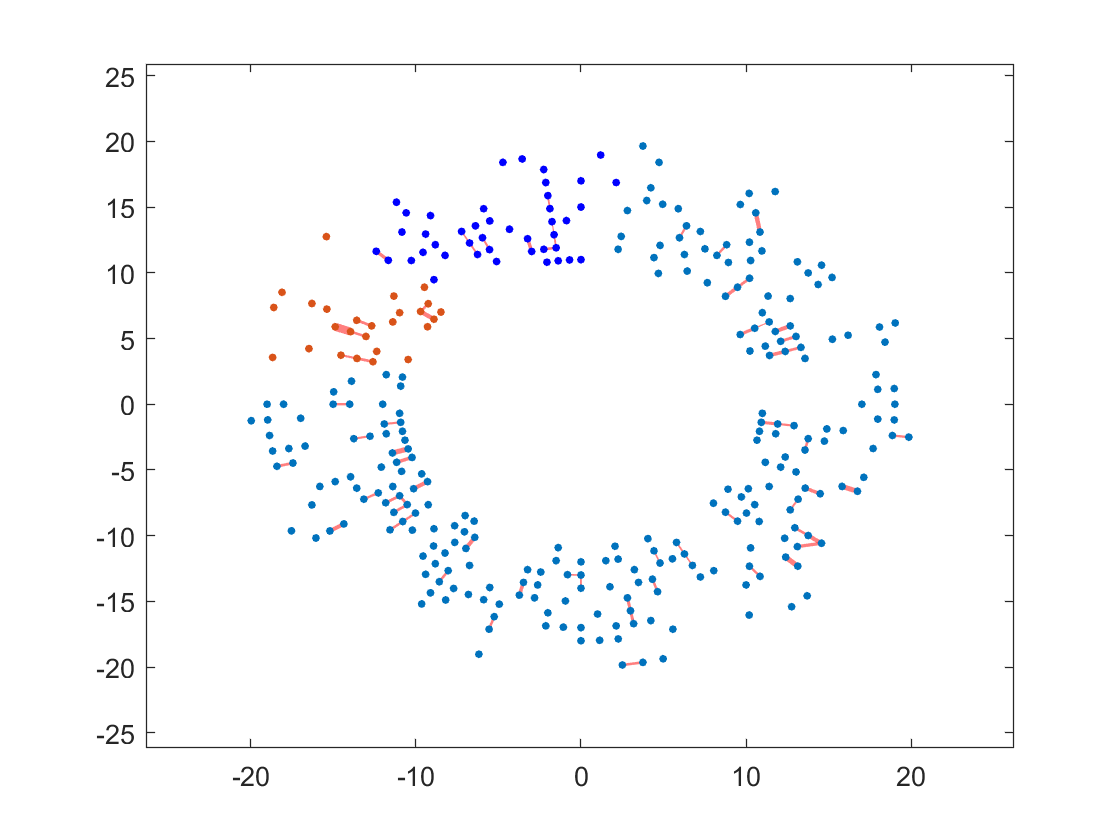

viewCrossSection(An, 10);

mean([An.Conduits.Length])

ans = 0.0275

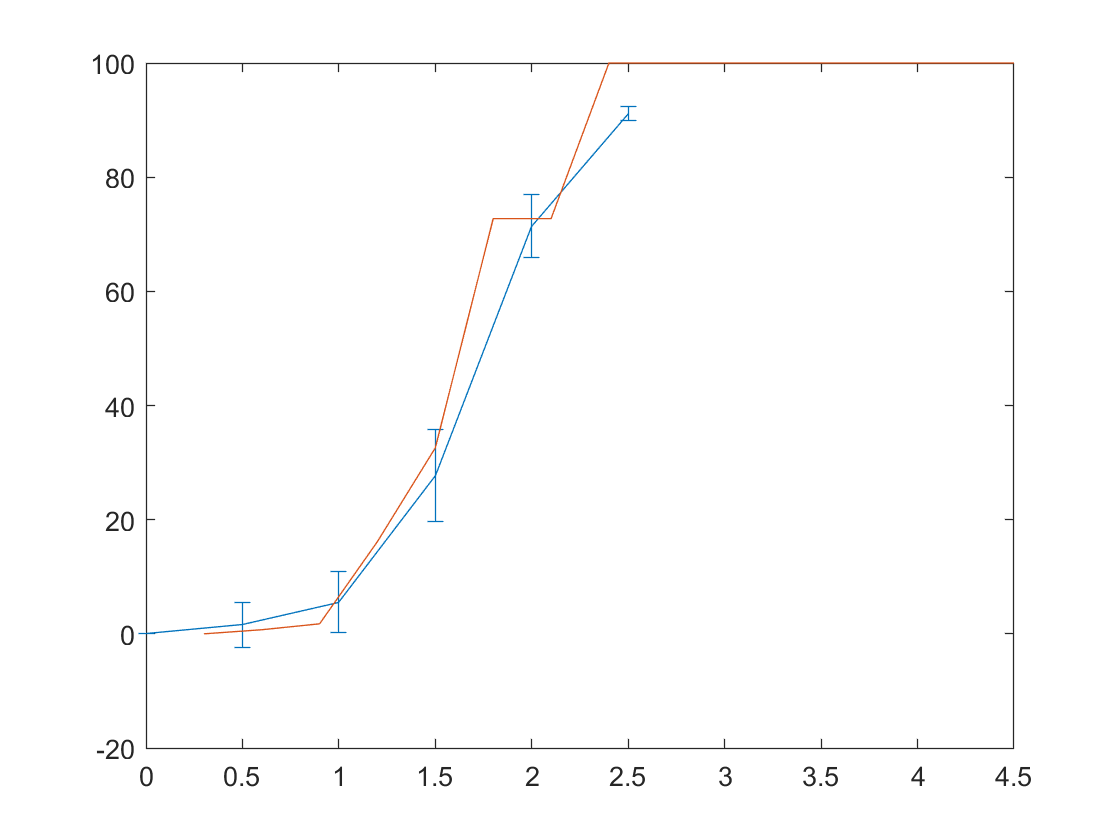


jt = 5; stepSize = 0.3; %MPa 
itmax = 15;  inEmb = 1; 
AvgBool = false;
[mVCAn.PLC,mVCAn.PV,mVCAn.Pressures,mVCAn.Kmax,mVCAn.Kini,mVCAn.voltot,mVCAn.embNb,...
    mVCAn.ncNb,Emb,Pen] = cavitation_process(An,jt,stepSize,itmax,inEmb,...
    AvgBool);

figure;
errorbar(-AnVC.P,AnVC.mean,AnVC.se)
hold on 
plot(mVCAn.Pressures, mVCAn.PLC)


[~,~,~,ktot,ktot_xa,~] =...
    compute_hydraulics(An.gCond,1e6,0,...
    {An.Dcross(1,:), An.Dcross(2,:), An.Dcross(3,:), An.Dcross(4,:)},...
    VAx);

disp(strcat('k_(xa) = ', num2str(ktot_xa), ' m^2/(MPa.s) or ',...
    num2str(ktot_xa*1e6/1e3), ' mg/(kPa.s.mm)'))

k_(xa) =0.0017966 m^2/(MPa.s) or1.7966 mg/(kPa.s.mm)



disp(strcat('k_(sa) = ', num2str(ktot*VAx*1e6/CN), ' m^2/(MPa.s) or ',...
    num2str(ktot*VAx*1e6/CN*1e6/1e3), ' mg/(kPa.s.mm)'))

k_(sa) =0.00057778 m^2/(MPa.s) or0.57778 mg/(kPa.s.mm)


## Acer saccharinum

% rowNb = 50; colNb = 10; depNb = 100;
% Pc = [0.88 0.88]; NPc = [0.925 0.925]; Pe_rad = [0.17 0.17]; Pe_tan = [0.1 0.1];
% radDist = ones(1, colNb); Lce = 2.81e-3;
% Dc = 35.29e-6; Dc_cv = 0.10;
% Dp = 7.8e-9; Dm = 6.7e-6; A = 2005; B = 1.0;
% fc = 0.18; fpf = 0.85;
% fap = 0.055;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Pore';
% 
% As = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%       e_mean,e_cv,Tm,Lp,ASPcalcmethod);
% 
% [gi_val, gi_val_cond, CN, CG, CG_cond, VAx]  = gi(As)
% viewCrossSection(As, 10);
% mean([As.Conduits.Length])
% 
% jt = 5; stepSize = 0.3; %MPa 
% itmax = 15;  inEmb = 1; 
% AvgBool = false;
% [mVCAs.PLC,mVCAs.PV,mVCAs.Pressures,mVCAs.Kmax,mVCAs.Kini,mVCAs.voltot,mVCAs.embNb,...
%     mVCAs.ncNb,Emb,Pen] = cavitation_process(As,jt,stepSize,itmax,inEmb,...
%     AvgBool);
% 
% figure;
% errorbar(-AsVC.P,AsVC.mean,AsVC.se)
% hold on 
% plot(mVCAs.Pressures, mVCAs.PLC)
% 
% [~,~,~,ktot,ktot_xa,~] =...
%     compute_hydraulics(As.gCond,1e6,0,...
%     {As.Dcross(1,:), As.Dcross(2,:), As.Dcross(3,:), As.Dcross(4,:)},...
%     VAx);
% 
% disp(strcat('k_(xa) = ', num2str(ktot_xa), ' m^2/(MPa.s) or ',...
%     num2str(ktot_xa*1e6/1e3), ' mg/(kPa.s.mm)'))
% 
% disp(strcat('k_(sa) = ', num2str(ktot*VAx*1e6/CN), ' m^2/(MPa.s) or ',...
%     num2str(ktot*VAx*1e6/CN*1e6/1e3), ' mg/(kPa.s.mm)'))


## Acer platanoides

% Dc = 25.99e-6; Dc_cv = 0.09;
% rowNb = 50; colNb = ceil(15 * (21.81e-6)^2 / Dc^2); depNb = 100;
% Pc = [0.85 0.85]; NPc = [0.924 0.924]; Pe_rad = [0.7 0.7]; Pe_tan = [0.15 0.15];
% radDist = ones(1, colNb); Lce = 2.81e-3;
% 
% Dp = 8.8e-9; Dm = 6.9e-6; A = 700; B = 1.2;
% fc = 0.38; fpf = 0.71;
% fap = 0.055;
% e_mean = 0.015;
% e_cv = 0.35;
% Tm = 234e-9;
% Lp = 654e-9;
% ASPcalcmethod = 'Pore';
% 
% Apl = XylemNet(rowNb,colNb,depNb,Pc,NPc,Pe_rad,Pe_tan,radDist, Lce,Dc,Dc_cv,Dp,Dm,A,B,fc,fpf,fap,...
%       e_mean,e_cv,Tm,Lp,ASPcalcmethod);
% 
% [gi_val, gi_val_cond, CN, CG, CG_cond, VAx]  = gi(Apl)
% viewCrossSection(Apl, 10);
% mean([Apl.Conduits.Length])

% jt = 5; stepSize = 0.3; %MPa 
% itmax = 15;  inEmb = 1; 
% AvgBool = false;
% [mVCApl.PLC,mVCApl.PV,mVCApl.Pressures,mVCApl.Kmax,mVCApl.Kini,mVCApl.voltot,mVCApl.embNb,...
%     mVCApl.ncNb,Emb,Pen] = cavitation_process(Apl,jt,stepSize,itmax,inEmb,...
%     AvgBool);
% 
% figure;
% errorbar(-AplVC.P,AplVC.mean,AplVC.se)
% hold on 
% plot(mVCApl.Pressures, mVCApl.PLC)
% 
% [~,~,~,ktot,ktot_xa,~] =...
%     compute_hydraulics(Apl.gCond,1e6,0,...
%     {Apl.Dcross(1,:), Apl.Dcross(2,:), Apl.Dcross(3,:), Apl.Dcross(4,:)},...
%     VAx);
% 
% disp(strcat('k_(xa) = ', num2str(ktot_xa), ' m^2/(MPa.s) or ',...
%     num2str(ktot_xa*1e6/1e3), ' mg/(kPa.s.mm)'))
% 
% disp(strcat('k_(sa) = ', num2str(ktot*VAx*1e6/CN), ' m^2/(MPa.s) or ',...
%     num2str(ktot*VAx*1e6/CN*1e6/1e3), ' mg/(kPa.s.mm)'))
